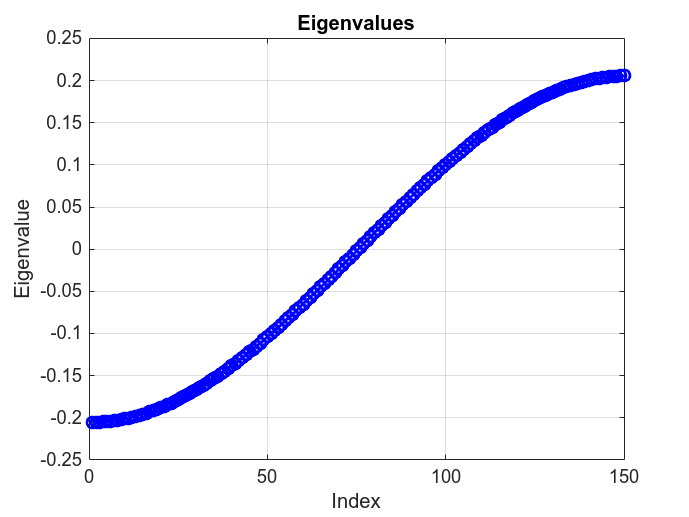

clear; clc;




%% ----------------------------------------------------
%  Helper function to convert "real imag real imag ..." rows → complex matrix
% ----------------------------------------------------
convert_to_complex = @(Mraw) ...
    Mraw(:,1:2:end) + 1i*Mraw(:,2:2:end);


%% ----------------------------------------------------
%  Load eigenvalues
% -----------------------------------------------------
Eraw = load('eigenvalues.txt');   % col1=Re, col2=Im
E = Eraw(:,1) + 1i*Eraw(:,2);

figure;
plot(real(E), 'bo-', 'LineWidth', 1.5); grid on;
xlabel('Index');
ylabel('Eigenvalue');
title('Eigenvalues');

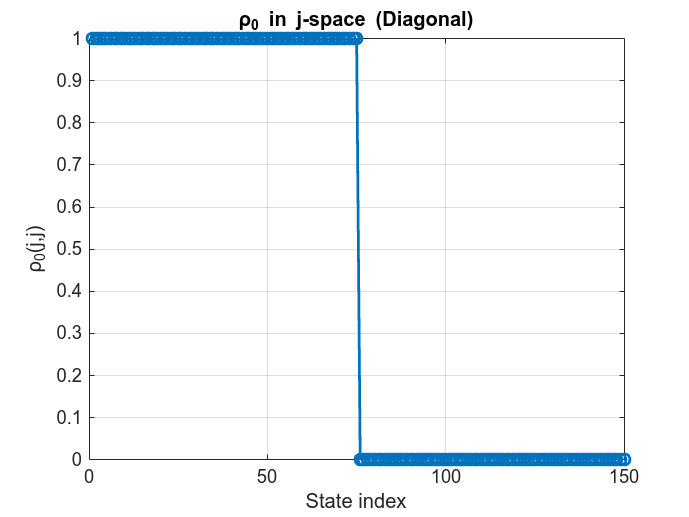






%% ----------------------------------------------------
%  Load rho0 in j-space (eigenbasis)
% -----------------------------------------------------
rho0j_raw = load('rho0_j_space.txt');
rho0_j = convert_to_complex(rho0j_raw);

figure;

plot(real(diag(rho0_j)), 'o-', 'LineWidth', 1.5);
grid on;
xlabel('State index');
ylabel('ρ_0(j,j)');
title('ρ_0 in j-space (Diagonal)');

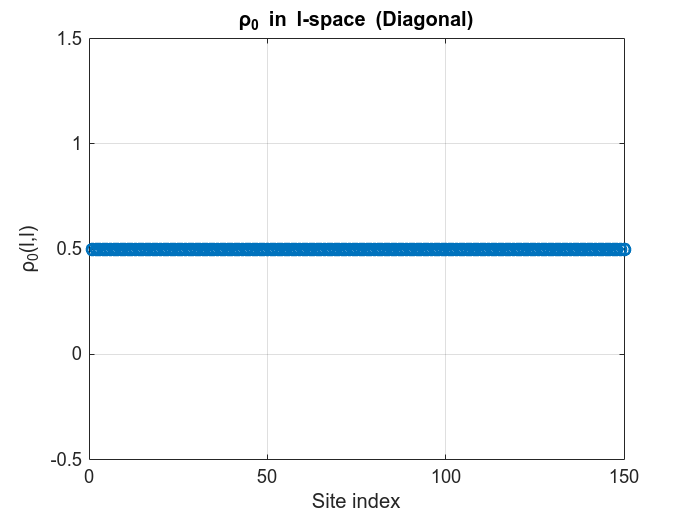





%% ----------------------------------------------------
%  Load rho0 in l-space (site basis)
% -----------------------------------------------------
rho0l_raw = load('rho0_l_space.txt');
rho0_l = convert_to_complex(rho0l_raw);

figure;

plot(real(diag(rho0_l)), 'o-', 'LineWidth', 1.5);
grid on;
xlabel('Site index');
ylabel('ρ_0(l,l)');
title('ρ_0 in l-space (Diagonal)');

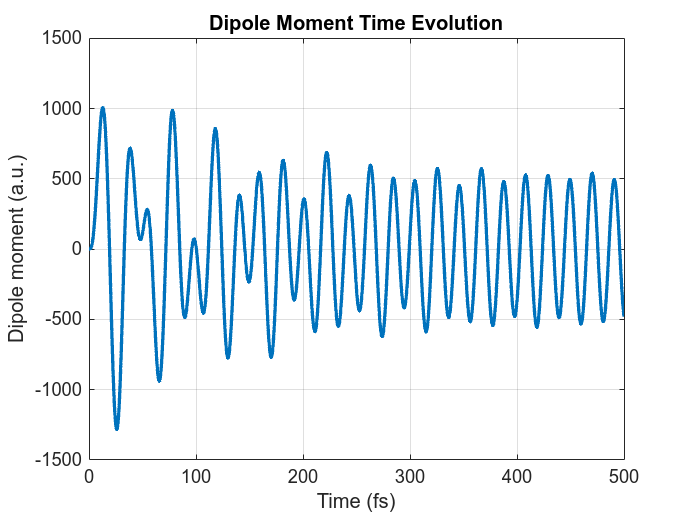



%% ----------------------------------------------------
%  Load dipole evolution data
% -----------------------------------------------------
dip = readmatrix('dipole_time_evolution.txt');
t      = dip(:,1);
d      = dip(:,2);

au_s = 2.41888e-17;
au_fs = au_s * 1e15;

t_fs = t * au_fs;

figure;
plot(t_fs, d, 'LineWidth', 1.8); grid on;
xlabel('Time (fs)');
ylabel('Dipole moment (a.u.)');
title('Dipole Moment Time Evolution');

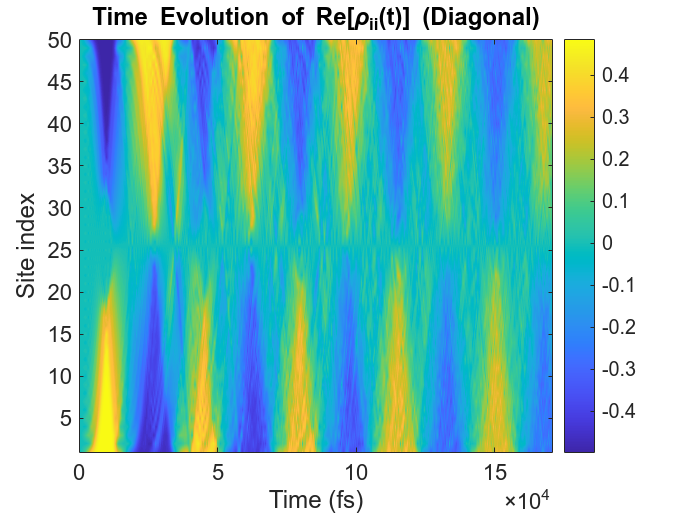


%% ----------------------------------------------------
%  Load rho(t) time evolution (one-file format)
% -----------------------------------------------------

fid = fopen('rho_time_evolution.txt','r');

header = fscanf(fid, '%d %d', 2);
T = header(1);     % number of time steps
N = header(2);     % matrix dimension

rho_diag_time = zeros(N, T);   % store ONLY diagonal evolution
time_rho = zeros(T,1);

for k = 1:T

    % read time value
    time_rho(k) = fscanf(fid, '%f', 1);

    % read the full NxN * (real imag) matrix
    raw = fscanf(fid, '%f', [2*N, N])';
    rho_real = raw(:,1:2:end);
    rho_imag = raw(:,2:2:end);
    rho = rho_real + 1i*rho_imag;

    % extract diagonal for contour plot
    rho_diag_time(:,k) = real(diag(rho));

end

fclose(fid);


%% ----------------------------------------------------
%  Contour plot of diagonal density evolution
% -----------------------------------------------------

figure;
contourf(time_rho/au_fs, 1:N, rho_diag_time, 80, 'LineColor', 'none');
colorbar;
xlabel('Time (fs)');
ylabel('Site index');
title('Time Evolution of Re[\rho_{ii}(t)] (Diagonal)');
set(gca, 'FontSize', 12);